%% Load Data
datasetname = 'feb11-imaging-intensity-calibration.mat';
if exist(datasetname) 
    load(datasetname); 
end


%% Go through all pixels (averaging 10 along rows for better s2n)

% Define range and averaging
ys = (100:3:180)';            % All Y pixels with atoms
xs = [90 93 96 99];   % Edges for the X averaging
% dxs = xs(2) - xs(1) - 1;    % # of pixels in each averaging bin

% Initialize empty variables
alpha_all = zeros(length(ys) * (length(xs)-1), 1);
ODreal_all = zeros(length(ys) * (length(xs)-1), 1);
xbins = length(xs)-1;
ybins = length(ys)-1;

% Process each bin
for i = 1:ybins
    for j = 1:xbins
        tODc = arrayfun(@(x) mean(mean(x.od( ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)) )),d1,'UniformOutput',true);
        tDI = arrayfun(@(x) mean(mean(x.woa(  ys(i)+1:ys(i+1)    ,xs(j)+1:xs(j+1)) - x.wa(ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)))),d1,'UniformOutput',true);
        [talpha,tODreal] = fitline_saturation_intensity_2(tODc,tDI,'plot',{0});
        alpha_all((i-1)*xbins + j) = talpha;
        ODreal_all((i-1)*xbins + j) = tODreal;
    end
end

% Save variables
res1.info = 'February 11 2016 dataset 1 results.';
res1.alpha_all = alpha_all;
res1.ODreal_all = ODreal_all;
save(datasetname,'res1','-append');

clearvars i j xbins ybins tODc tDI talpha tODreal alpha_all ODreal_all xs ys



%% Go through all pixels (averaging 10 along rows for better s2n)

% Define range and averaging
ys = (100:3:180)';            % All Y pixels with atoms
xs = [90 93 96 99];   % Edges for the X averaging
% dxs = xs(2) - xs(1) - 1;    % # of pixels in each averaging bin

% Initialize empty variables
alpha_all = zeros(length(ys) * (length(xs)-1), 1);
ODreal_all = zeros(length(ys) * (length(xs)-1), 1);
xbins = length(xs)-1;
ybins = length(ys)-1;

% Process each bin
for i = 1:ybins
    for j = 1:xbins
        tODc = arrayfun(@(x) mean(mean(x.od( ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)) )),d2,'UniformOutput',true);
        tDI = arrayfun(@(x) mean(mean(x.woa(  ys(i)+1:ys(i+1)    ,xs(j)+1:xs(j+1)) - x.wa(ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)))),d2,'UniformOutput',true);
        [talpha,tODreal] = fitline_saturation_intensity_2(tODc,tDI,'plot',{0});
        alpha_all((i-1)*xbins + j) = talpha;
        ODreal_all((i-1)*xbins + j) = tODreal;
    end
end

% Save variables
res2.info = 'February 11 2016 dataset 2 results.';
res2.alpha_all = alpha_all;
res2.ODreal_all = ODreal_all;
save(datasetname,'res1','-append');

clearvars i j xbins ybins tODc tDI talpha tODreal alpha_all ODreal_all xs ys


%% Load analyzed data
datasetname = 'feb11-imaging-intensity-calibration.mat';
load(datasetname,'res1','res2');

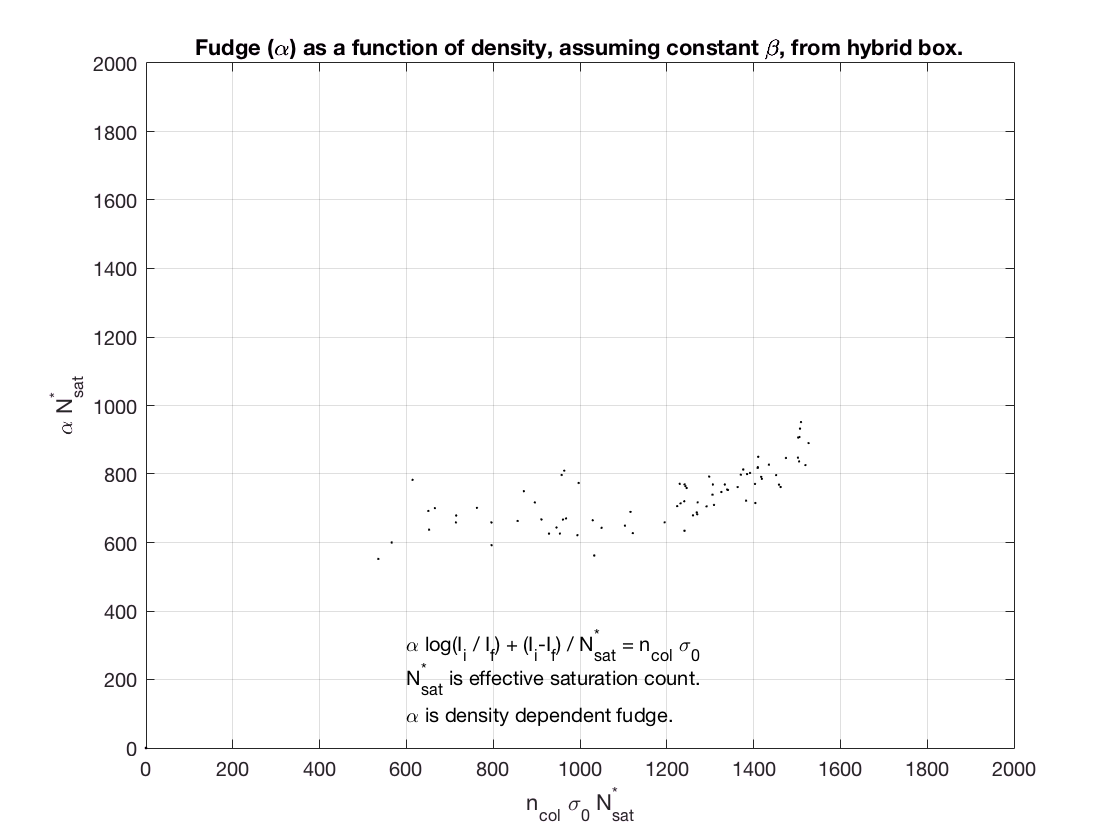

%% Plots
figure;
plot(res1.ODreal_all,res1.alpha_all,'k.');
xlabel('n_{col} \sigma_0 N_{sat}^*'); xlim([0 2000]);
ylabel('\alpha N_{sat}^*'); ylim([0 2000]);
grid on;
title('Fudge (\alpha) as a function of density, assuming constant \beta, from hybrid box.');
text(600,300,'\alpha log(I_i / I_f) + (I_i-I_f) / N_{sat}^* = n_{col} \sigma_0');
text(600,200,'N_{sat}^{*} is effective saturation count.');
text(600,100,'\alpha is density dependent fudge.');

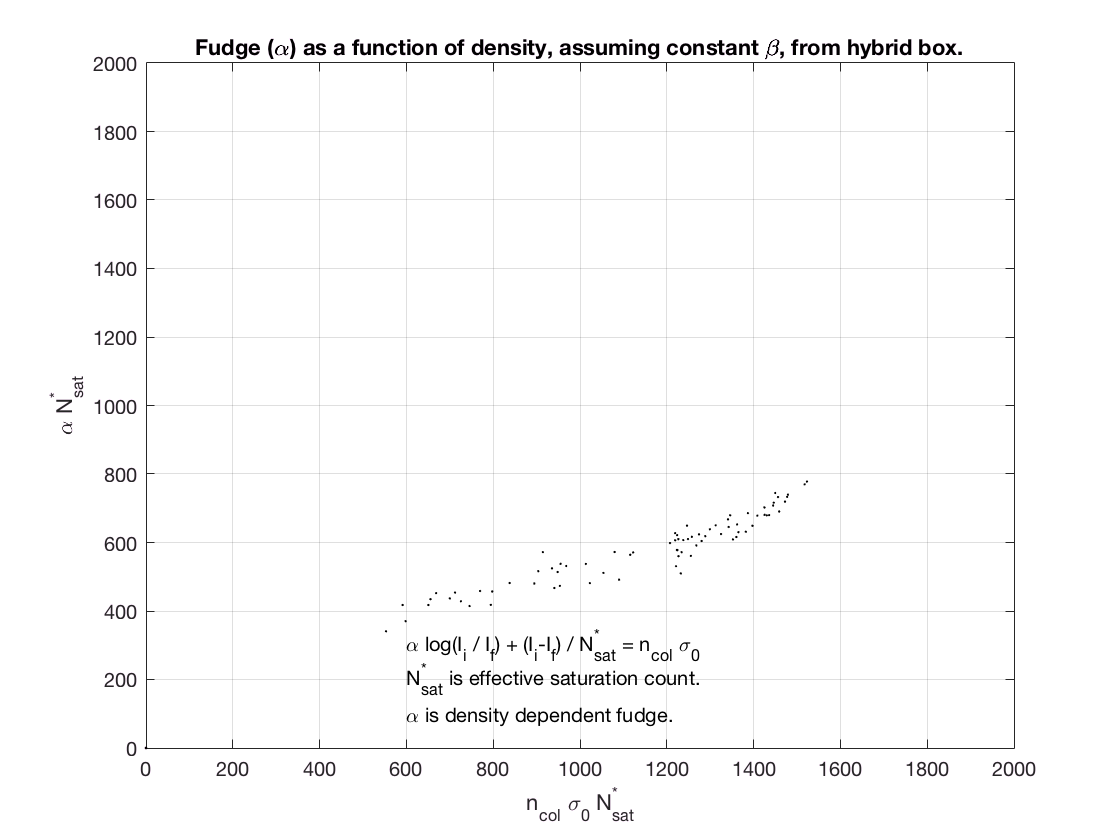


%% Plots
figure;
plot(res2.ODreal_all,res2.alpha_all,'k.');
xlabel('n_{col} \sigma_0 N_{sat}^*'); xlim([0 2000]);
ylabel('\alpha N_{sat}^*'); ylim([0 2000]);
grid on;
title('Fudge (\alpha) as a function of density, assuming constant \beta, from hybrid box.');
text(600,300,'\alpha log(I_i / I_f) + (I_i-I_f) / N_{sat}^* = n_{col} \sigma_0');
text(600,200,'N_{sat}^{*} is effective saturation count.');
text(600,100,'\alpha is density dependent fudge.');

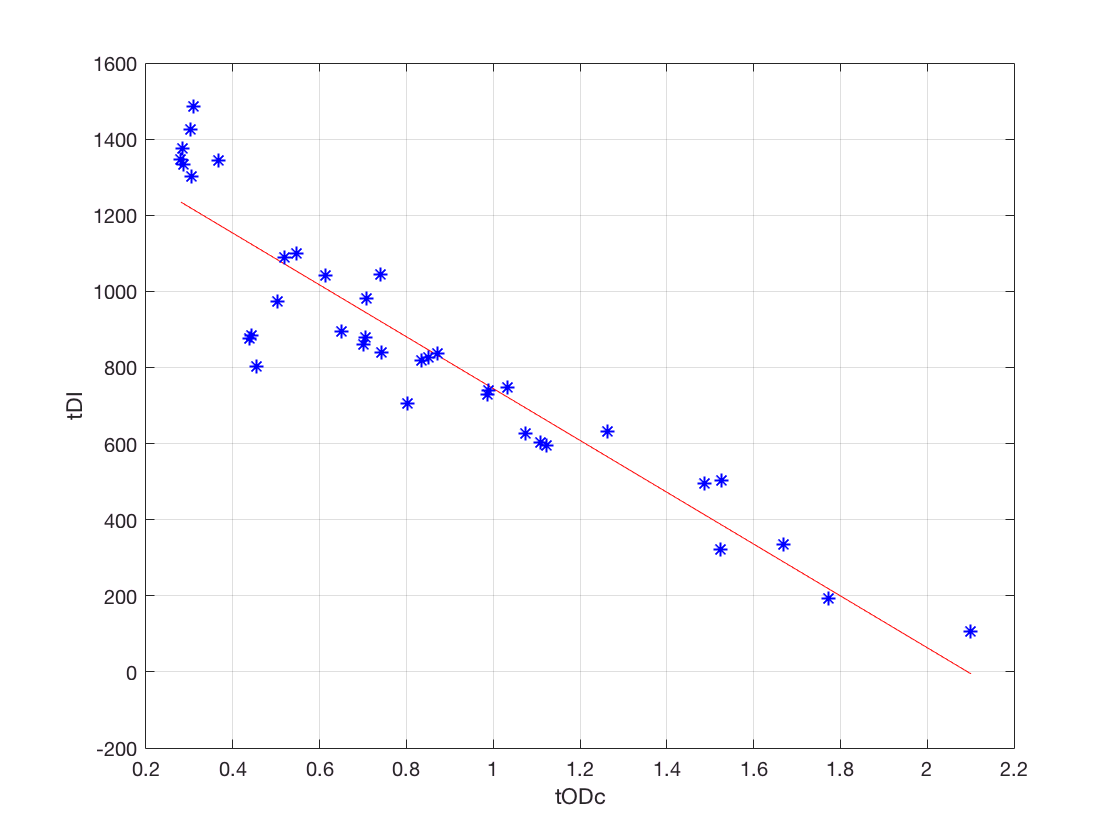

%% Tests for fits
i = 15; 
j = 2;

ys = (100:3:180)';            % All Y pixels with atoms
xs = [90 93 96 99];   % Edges for the X averaging
tODc = arrayfun(@(x) mean(mean(x.od( ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)) )),d2,'UniformOutput',true);
tDI = arrayfun(@(x) mean(mean(x.woa(  ys(i)+1:ys(i+1)    ,xs(j)+1:xs(j+1)) - x.wa(ys(i)+1:ys(i+1),xs(j)+1:xs(j+1)))),d2,'UniformOutput',true);
[talpha,tODreal] = fitline_saturation_intensity_2(tODc,tDI,'plot',{1});

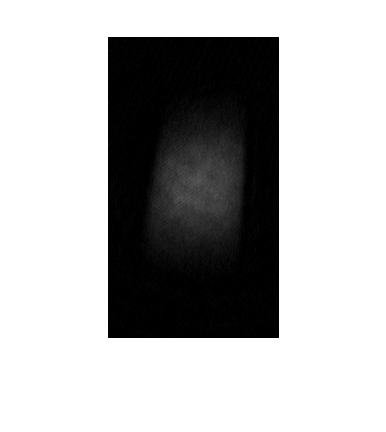

imshow(d1(5).od)